# Support Vector Machines

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code loads the pump features.

dataTrain = readtable("data\pumpFeaturesSVM.xlsx", Sheet="dataTrain")

dataTrain = 294×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean  

dataTest = readtable("data\pumpFeaturesSVM.xlsx", Sheet="dataTest")

dataTest = 126×85 table
    wMotor_mean    wMotor_std    wMotor_fftPeakIdx    wMotor_skewness    wMotor_kurtosis    wMotor_peak2peak    wMotor_peak2rms    wMotor_rms    wMotor_mad    wMotor_csRange    wMotor_pLow    wMotor_pMid    wMotor_pHigh    wMotor_pKur    iMotor_mean    iMotor_std    iMotor_fftPeakIdx    iMotor_skewness    iMotor_kurtosis    iMotor_peak2peak    iMotor_peak2rms    iMotor_rms    iMotor_mad    iMotor_csRange    iMotor_pLow    iMotor_pMid    iMotor_pHigh    iMotor_pKur    qIn_mean   

## Task 1

To construct a Support Vector Machine (SVM), use the `fitcsvm` function.

`svmModel` `=` `fitcsvm``(``tableData``,``...`

    `"``ResponseVariable``"``)``;`

mdlSVM = fitcsvm(dataTrain, "faultCode");

Evaluate model

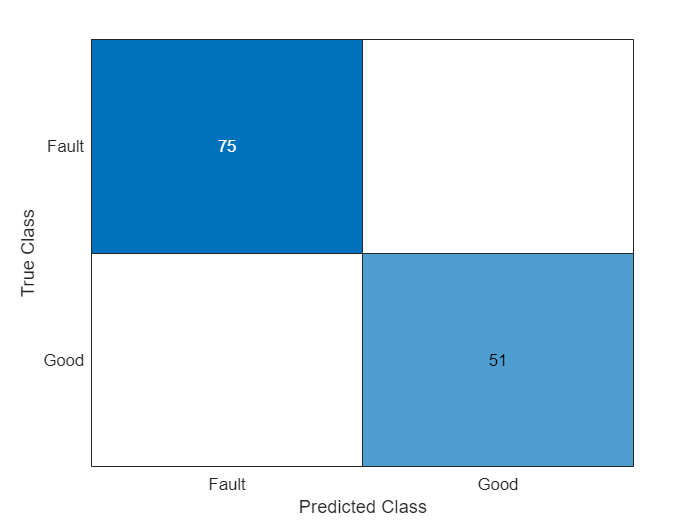

Training Error: 0
Loss: 0


evalModel(dataTest, mdlSVM)

## Task 2

How did the model separate the groups? The optimal hyperplane of the SVM optimization is influenced by the scale of the input data. Therefore, it is recommended to standardize the data when using this algorithm. You can do this prior to training using the `normalize` function. Alternatively, you can set the `"Standardize"` property in the model to `true`. 

`svmModel` `=` `fitcsvm``(``tableData``,``...`

    `"ResponseVariable"``,``... `

    `"Standardize"``,``true``)``;`

mdlSVM = fitcsvm(dataTrain, "faultCode", ...
    "Standardize", true);

Evaluate model

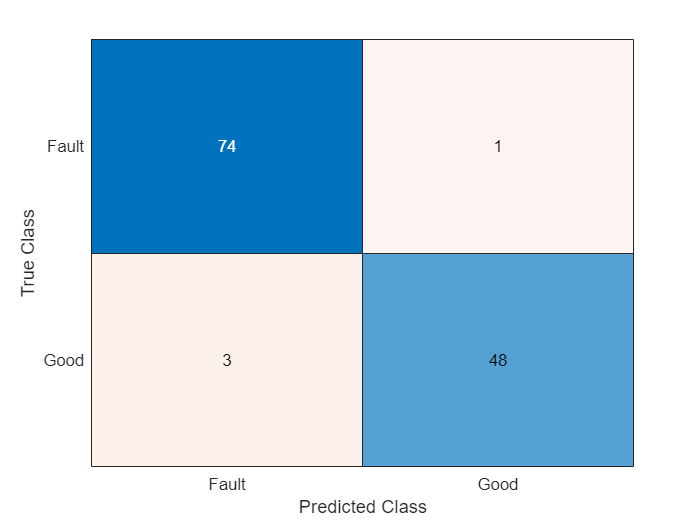

Training Error: 0.0034014
Loss: 0.031901


evalModel(dataTest, mdlSVM)

## Task 3

By default, `fitcsvm` uses a linear support vector. You can modify this by changing the `"KernelFunction"` property.

mdlSVM = fitcsvm(dataTrain, "faultCode", ...
    "Standardize", true, ...
    "KernelFunction", "polynomial");

Evaluate model

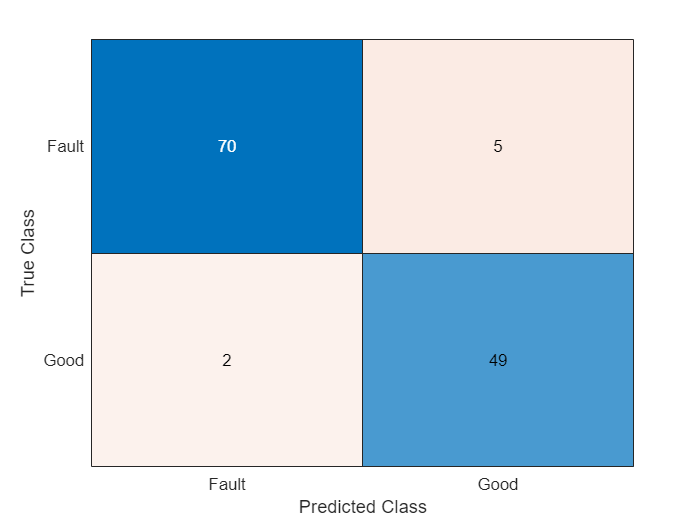

Training Error: 0.0034014
Loss: 0.055462


evalModel(dataTest, mdlSVM)

Do not edit. This function is used to evaluate a model by displaying the confusion chart, training error, and test loss.

function evalModel(dataTest, mdl)
    confusionchart(dataTest.faultCode, predict(mdl, dataTest))
    disp("Training Error: " + num2str(resubLoss(mdl)))
    disp("Loss: " + num2str(loss(mdl, dataTest)))
end